clear;
close all

if ispc
    addpath('..\..\audio_files');
    addpath('..\..\sim_environment');
else
    addpath('../../audio_files');
    addpath('../../sim_environment');
end

% Load ATFs
load Computed_RIRs

% Load measured HRTFs
load HRTF
% Load binaural signal
load binaural_sig

% run session 1
%run SOE_skeleton.mlx

## Generate noise at microphone

SNR_bubble = 5; SNR_white = 30;
noise_filename{1} = 'Babble_noise1.wav';noise_filename{2} = 'White_noise1.wav';

noise_babble = generate_noise(noise_filename{1},binaural_sig(:,1),fs_RIR,SNR_bubble,RIR_noise,siglength);
noise_white  = generate_noise(noise_filename{2},binaural_sig(:,1),fs_RIR,SNR_white,RIR_noise,siglength);



%% Exercise 3.1: ## Obtain the noisy microphone signals as outlined in the session document.
%
% SOME CONVENTIONS:
%
% Your clean speech signal should be called "speech" and is a binaural signal such that:
% speech = [speech_L speech_R]  % speech_L and speech_R are the clean binaurally synthesised speech signals from session 1
%
% Your noises should be stored in one binaural variable called "noise"

speech = binaural_sig;
noise = noise_white + noise_babble;
% noise = noise_babble;
% Create noisy mic signals in the time domain:
y_TD = speech + noise;  % stacked microphone signals
%soundsc(y_TD,fs_RIR)
snrb = snr(speech(:,1),noise_babble(:,2));
snrw = snr(speech(:,1),noise_white(:,2));

%% Apply WOLA analysis to observe signals in the STFT domain, Apply the SPP.

fs = fs_RIR;    % sampling freq
nfft = 512;    % number of DFT points
window = sqrt(hann(nfft,'periodic')); % analysis window
noverlap = 2;   % factor for overlap. noverlap = 2 corresponds to 50% overlap
time = 0:1/fs:((size(binaural_sig,1)-1)/fs);


% ## Apply the WOLA analysis to the noisy mic. signals, the speech, and the noise.
[y_STFT,f] = WOLA_analysis(y_TD,fs_RIR,window,nfft,noverlap) ;% To complete
[n_STFT,~] = WOLA_analysis(noise,fs_RIR,window,nfft,noverlap) ;% To complete
[x_STFT,f] = WOLA_analysis(speech,fs_RIR,window,nfft,noverlap) ;% To complete


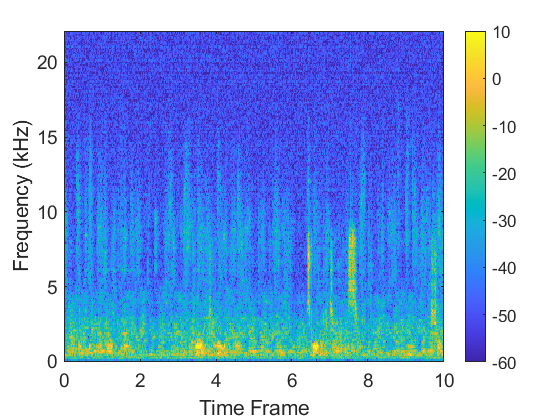


% Observe the STFT
clow = -60; chigh = 10; % lower and upper limits for signal power in spectrogram (can change for different resolutions)
[N_freqs, N_frames] = size(x_STFT(:,:,1));

figure;
imagesc(time, f/1000, mag2db(abs(y_STFT(:,:,1))), [clow, chigh]); colorbar;
axis xy; set(gca,'fontsize', 14);
set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')

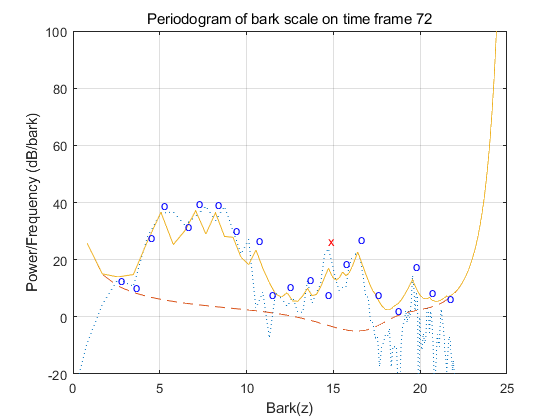


% 
TY_Mask = zeros(N_freqs,N_frames);
TS_Mask = zeros(N_freqs,N_frames);
TN_Mask = zeros(N_freqs,N_frames);
num_mics = 2;
%for m = 1:num_mics
  for t = 1:N_frames

    %  [TY_Mask(:,t),bark] = mask_cal(y_STFT(:,t,1),f,fs,nfft,t);
       [TX_Mask(:,t),bark] = mask_cal(x_STFT(:,t,1),f,fs,nfft,t);
    %  [TN_Mask(:,t),bark] = mask_cal(n_STFT(:,t,1),f,fs,nfft,t);
      
   end

%end 
